# VD Workbench

%clear; %clf; % Remember to clear after importing a different file / making major changes!

% MODES
GTYPE = "IMU";      % Switches the accelerometer used for calculations
SPEEDMODE = "GPS";  % Switches the speed data used for calculations
DATATYPE = "LapsBeacon";   % Changes the lap finding and run trimming behavior 

% IMPORT
% Uncomment the first line for a GUI file select
% [filename, path] = uigetfile('*.csv', 'Select First MoTeC Output File');
filename = "Colin6LapEndurance.csv";
path = "./Data";
run = motecImport(filename, path);

% TRIM
if DATATYPE == "LapsBeacon"
    li = find(run.LapNumber > min(run.LapNumber) & run.LapNumber < max(run.LapNumber));
    run = run(li,:); % trim the original run variable
end

% HELPER VARIABLES 
[gLat, gLong, speed, time] = SetupVariables(run, GTYPE, SPEEDMODE);
car = FB2223();
lapZero = min(run.LapNumber) - 1; 
lapMax = max(run.LapNumber); 


## Calc Code

[UA, AA, WA] = UndersteerAngle(gLat,speed,run.SteeredAngle,car);

%[TA, TAS] = ThrottleAcceptance(run, gLat, time) 
% Throttle Acceptance needs to be re-written with less error-prone logic

for i = 1:lapMax-lapZero
    [i1, i2] = LapBounds(run, lapZero, lapMax, i);
    
    Lap(i) = i;
    lapTimes(i) = time(i2) - time(i1);
    
    [UA1, AA1, WA1] = UndersteerAngle(gLat(i1:i2),speed(i1:i2),run.SteeredAngle(i1:i2),car);
    avgUA(i) = mean(UA1);
    
    [GO, GB, GA, GC, GAero] = GripSubsets(gLat(i1:i2), gLong(i1:i2), speed(i1:i2));
    avgGO(i) = mean(GO);
    avgGB(i) = mean(abs(GB));
    avgGA(i) = mean(GA);
    avgGC(i) = mean(GC);
    avgGAero(i) = mean(GAero);
end

OverallGrips = GripSubsets(gLat, gLong, speed);


## Plotting Code

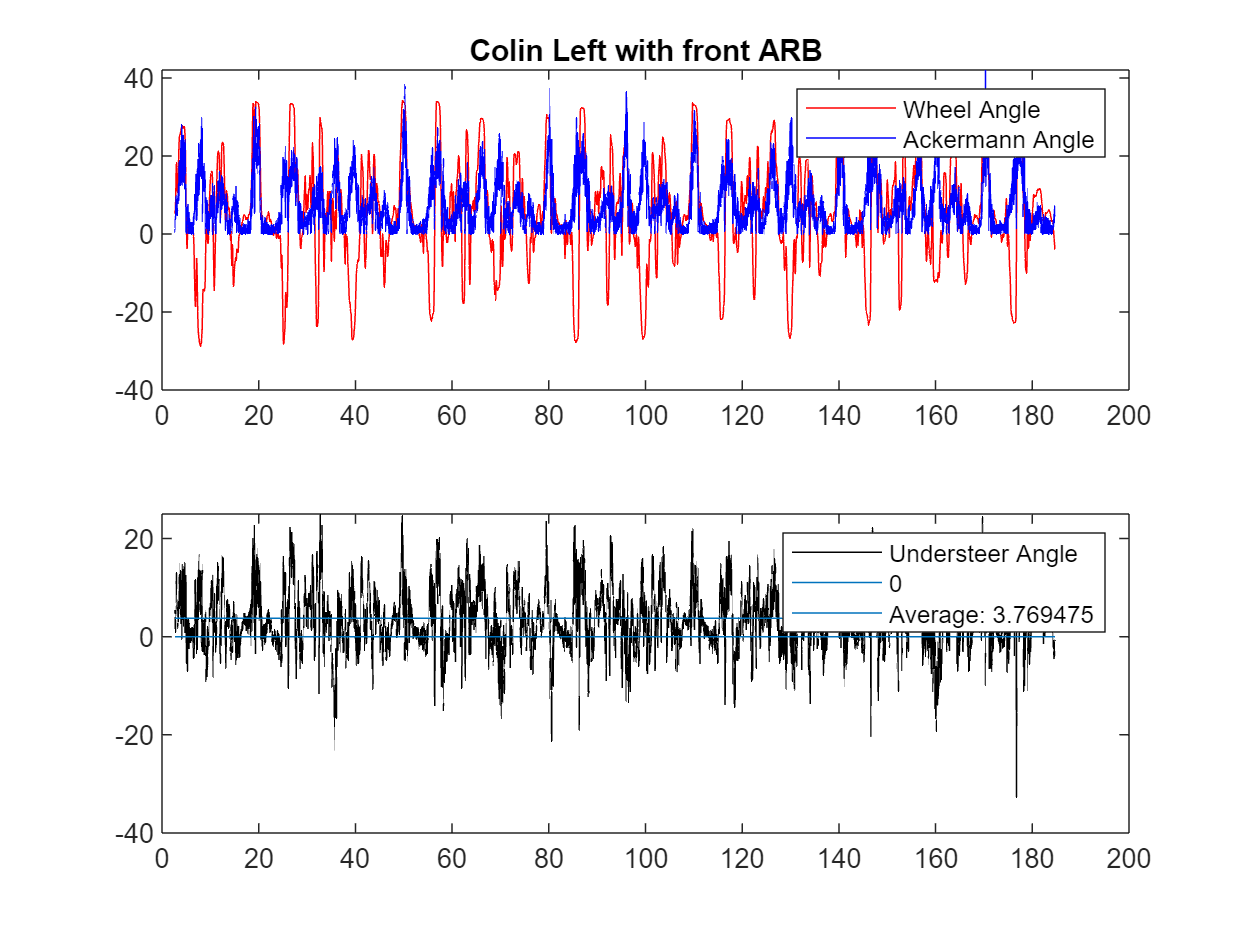

clf;
figure
UndersteerDisplay("Colin Left with front ARB", time, WA, AA, UA);

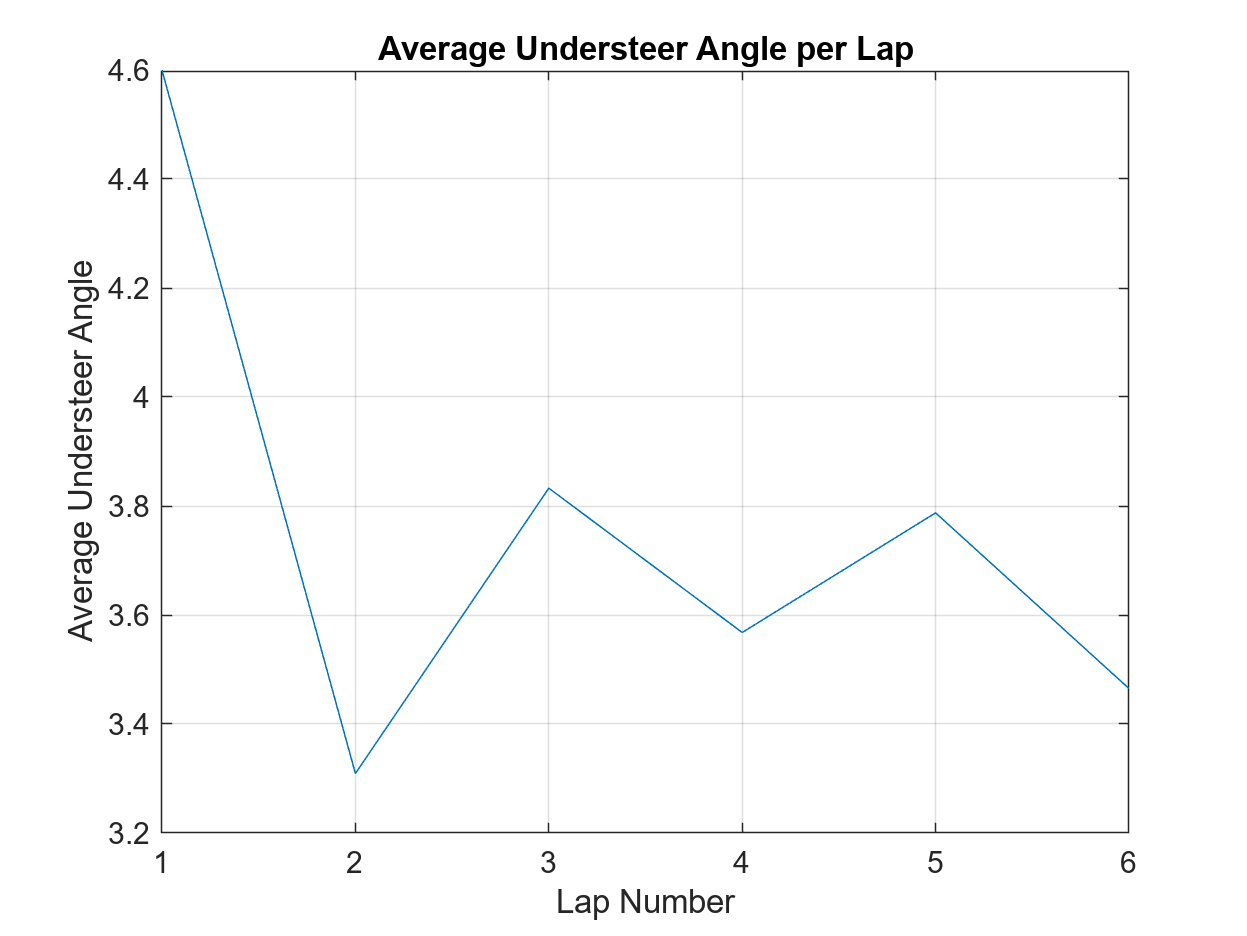


figure
plot(Lap, avgUA); grid on; title('Average Understeer Angle per Lap'); 
xlabel('Lap Number'); ylabel('Average Understeer Angle')

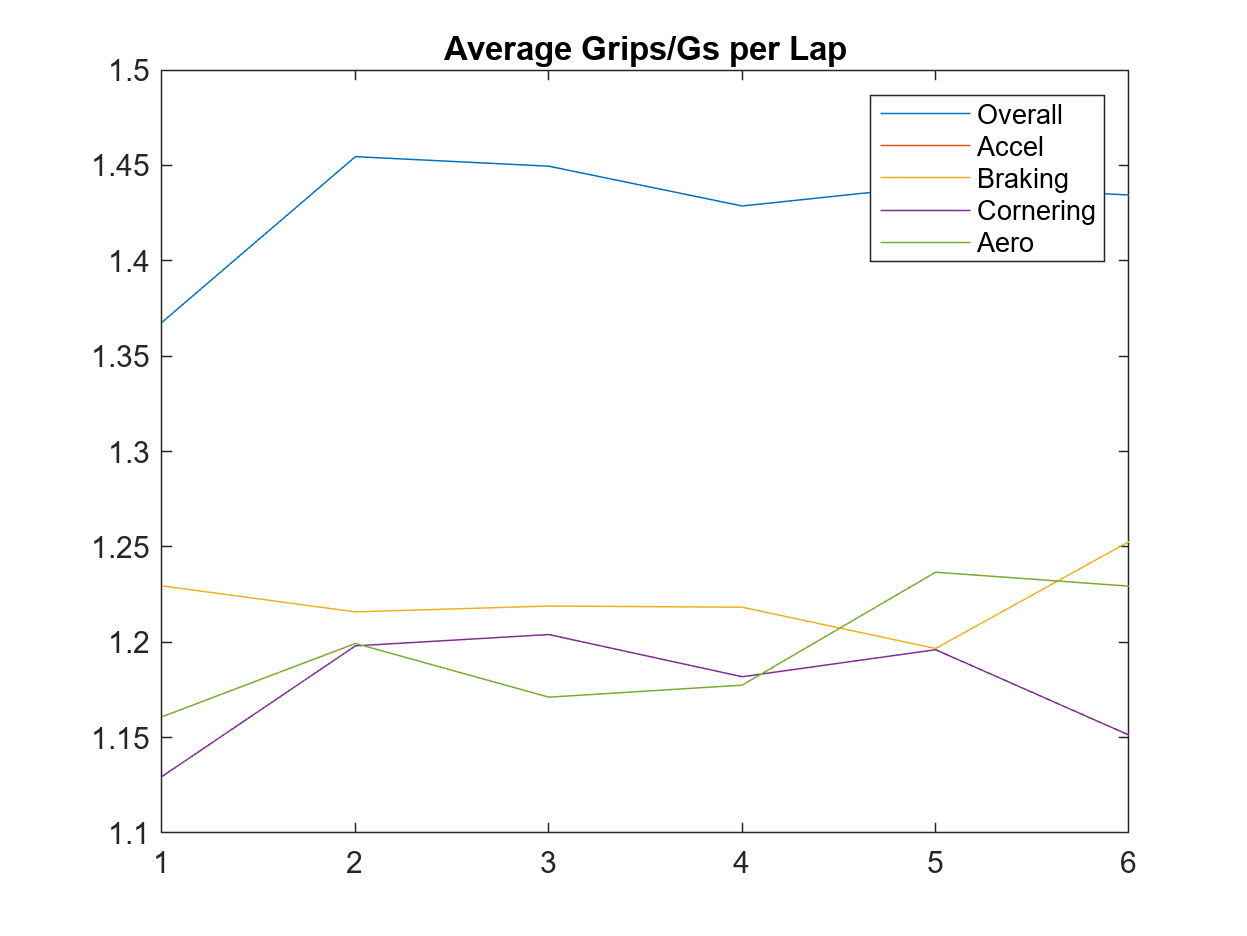


figure
plot(Lap, avgGO, ...
    Lap, avgGA, ...
    Lap, avgGB, ...
    Lap, avgGC, ...
    Lap, avgGAero)
title("Average Grips/Gs per Lap")
legend('Overall','Accel','Braking','Cornering','Aero')

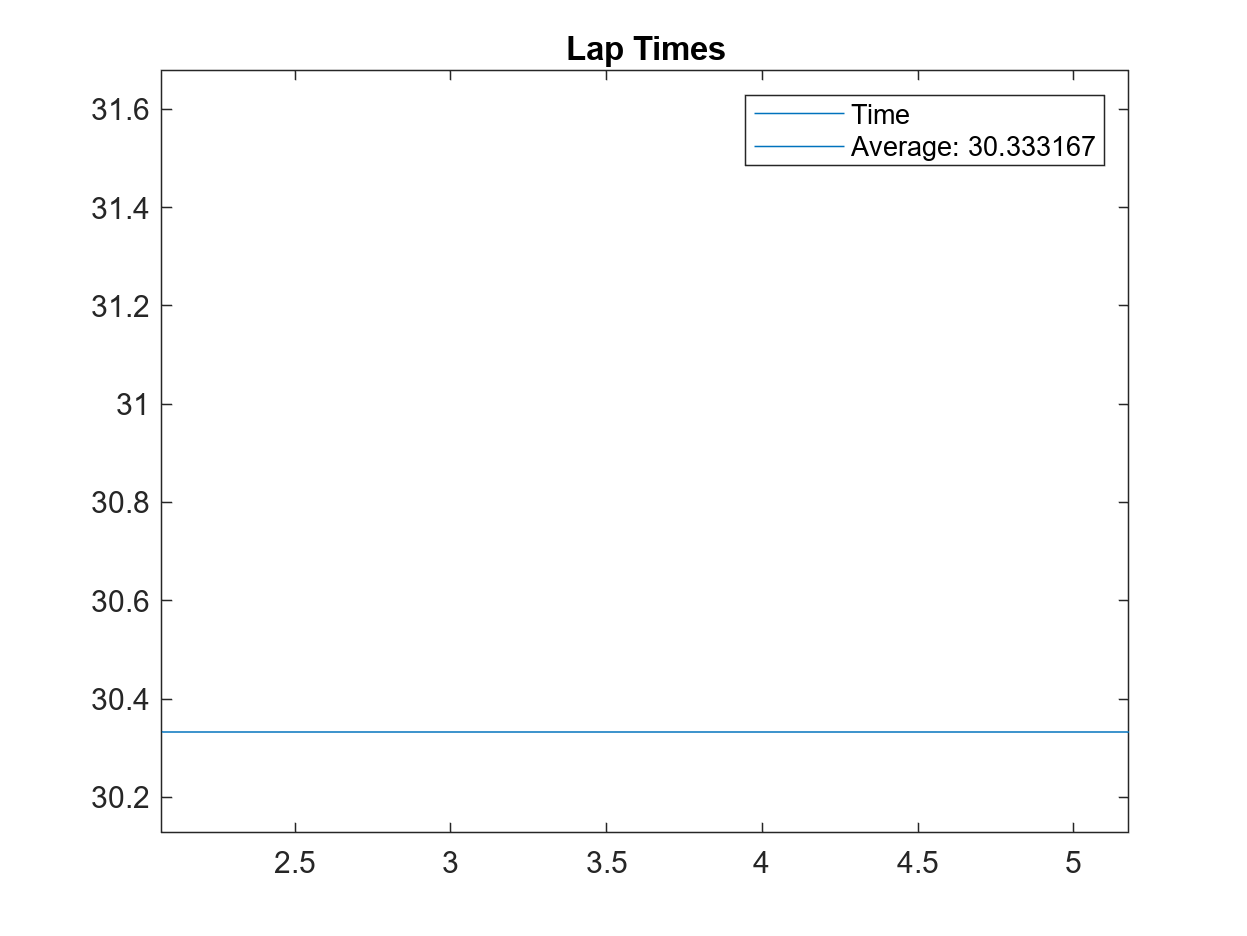


figure
plot(Lap,lapTimes)
title("Lap Times")
line([1 max(Lap)], [mean(lapTimes) mean(lapTimes)])
legend('Time', sprintf('Average: %f', mean(lapTimes)))

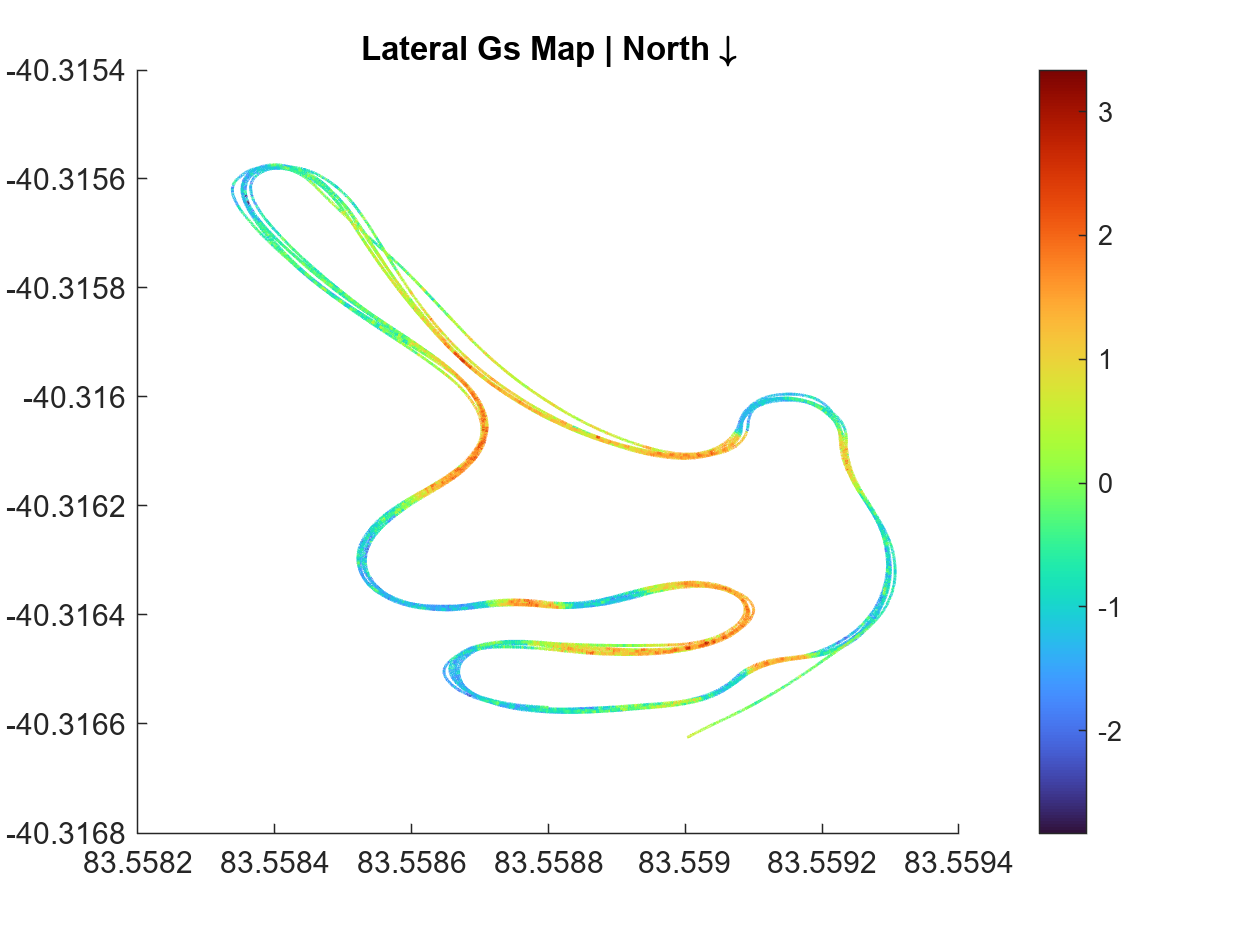


figure 
TrackDisplay(-run.GPSLongitude, -run.GPSLatitude, gLat)
title("Lateral Gs Map | North \downarrow")